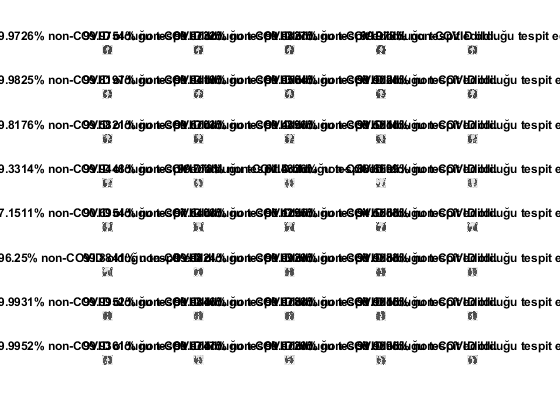

% clear all
% close all 
% clc 

myFolder = 'C:\model\testdata';
images = imageDatastore(myFolder);
uzunluk = length(images.Files);
for i = 1 : uzunluk
    img = imread(images.Files{i});
    image=imresize(img,[227 227]);
    [label,score] = classify(net,image);
    subplot(8,5,i);
    imshow(image);
    title(max(score)*100+"% " + string(label) + " olduğu tespit edildi.");
    
    % path = strcat('write\',num2str(i),'.jpg') 
    % imwrite(img, path) % yazmak için
    % pause(0.2)

end